本脚本的目的大概是，找到在某一个确定的B的大小时，这个边界点（2body和3body）的相互作用强度。

首先，对两体的solver，要分别找到他们的一个解。

然后，在这个解的基础上，扫相互作用强度，直到能量发生交叉，把这个点定为初始点。

twobodyini = -2.2601 - 0.0270i

threebodyini = -2.2002 - 0.7477i

时间已过 1451.330932 秒。


时间已过 2273.634086 秒。


时间已过 2273.659356 秒。


时间已过 3093.702774 秒。


时间已过 3093.715762 秒。


时间已过 3914.611755 秒。


时间已过 3914.623852 秒。


时间已过 4743.987492 秒。


时间已过 4744.005237 秒。


时间已过 5616.447814 秒。


时间已过 5616.462014 秒。


时间已过 6467.471736 秒。


时间已过 6467.484049 秒。


时间已过 7324.972124 秒。


时间已过 7324.983430 秒。


时间已过 8172.809714 秒。


时间已过 8172.821525 秒。


时间已过 9049.565419 秒。


时间已过 9049.584941 秒。


时间已过 9934.445365 秒。


时间已过 9934.458048 秒。


时间已过 10805.921377 秒。


时间已过 10805.933654 秒。


时间已过 11691.601498 秒。


时间已过 11691.614772 秒。


时间已过 12575.704371 秒。


时间已过 12575.727866 秒。


时间已过 13454.607569 秒。


时间已过 13454.619871 秒。


时间已过 14340.054938 秒。


时间已过 14340.066051 秒。


时间已过 15220.788026 秒。


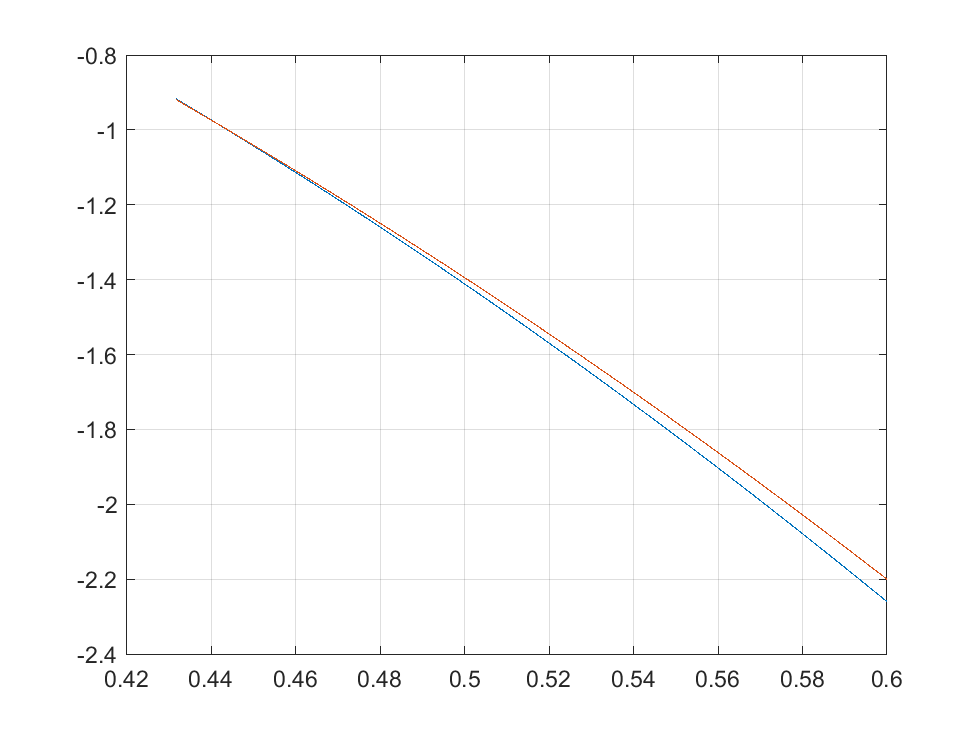

%找到一个解
%初始化定义
clear
dbstop if error
B=0.499i;
eta=40/6;
options=optimset("Display","off");
warning off
kfasneg1=0.6;tic
if isreal(B)==1 %判断B是否是实数
    output1=zeros(1,10);
    output2=zeros(1,20);
    
    E1=linspace(-4,0,length(output1));
    for i=1:length(E1)
        output1(i)=dimersolver(E1(i),kfasneg1,eta,B);
        if output1(i)>0
            E1=E1(1:i);
            E2=linspace(E1(i-1),E1(i),length(output2));
            for j=1:length(E2)
                output2(j)=dimersolver(E2(j),kfasneg1,eta,B);
                if output2(j)>0
                    output2=output2(1:j);
                    E2=E2(1:j);
                    twobodyini=fsolve(@(E) dimersolver(E,kfasneg1,eta,B),E2(j-1),options)
                    break
                end
            end
            break
        end
    end
    figure
    plot(E2,output2)
    grid on
    output1=zeros(1,10);
    output2=zeros(1,20);
    tic;
    E1=linspace(-4,0,length(output1));
    for i=1:length(E1)
        output1(i)=borromeansolver(E1(i),kfasneg1,eta,B);toc;
        if output1(i)>0
            E1=E1(1:i);
            output1=output1(1:i);
            E2=linspace(E1(i-1),E1(i),length(output2));
            for j=1:length(E2)
                output2(j)=borromeansolver(E2(j),kfasneg1,eta,B);toc;
                if output2(j)>0
                    output2=output2(1:j);
                    E2=E2(1:j);
                    threebodyini=fsolve(@(E) borromeansolver(E,kfasneg1,eta,B),E2(j-1),options)
                    toc
                    break
                end
            end
            break
        end
    end
    figure
    plot(E2,output2)
    grid on
    
    S1=sign(threebodyini-twobodyini);
    kfasneg2=kfasneg1+S1*0.6;
    kfasneg=linspace(kfasneg1,kfasneg2,10);
    [Eb2,Eb3]=deal(zeros(1,length(kfasneg)));
    Eb2=twobodyini;Eb3=threebodyini;
    toc;
    for i=2:length(kfasneg)
        Eb2(i)=fsolve(@(E) dimersolver(E,kfasneg(i),eta,B),Eb2(i-1),options);toc
        Eb3(i)=fsolve(@(E) borromeansolver(E,kfasneg(i),eta,B),Eb3(i-1),options);toc
        S2=sign(Eb3(i)-Eb2(i));
        if S1*S2<0
            Eb3=Eb3(1:i);
            Eb2=Eb2(1:i);
            kfasneg=kfasneg(1:i);
            break
        end
        
    end
    figure
    hold on
    plot(kfasneg,Eb2)
    plot(kfasneg,Eb3)
else %B是虚数的情况
   twobodyini=fsolve(@(E) dimersolver(E,kfasneg1,eta,B),complex(-6,-6),options)
   threebodyini=fsolve(@(E) borromeansolver(E,kfasneg1,eta,B),twobodyini-complex(2,2),options)
   S1=sign(-real(threebodyini-twobodyini));
   kfasneg2=kfasneg1+S1*0.2;
   kfasneg=linspace(kfasneg1,kfasneg2,20);
   [Eb2,Eb3]=deal(zeros(1,length(kfasneg)));
   Eb2(1)=twobodyini;Eb3(1)=threebodyini;
   for i=2:length(kfasneg)
        Eb2(i)=fsolve(@(E) dimersolver(E,kfasneg(i),eta,B),Eb2(i-1),options);toc
        Eb3(i)=fsolve(@(E) borromeansolver(E,kfasneg(i),eta,B),Eb3(i-1),options);toc
        S2=sign(Eb3(i)-Eb2(i));
        if S1*S2>0
            Eb3=Eb3(1:i);
            Eb2=Eb2(1:i);
            kfasneg=kfasneg(1:i);
            break
        end
   end
   figure
   plot(kfasneg,Eb2)
   hold on 
   plot(kfasneg,Eb3)
   grid on
   
   
    
end


save(strcat('data_B',num2str(B),'.mat'),'B','kfasneg')